## LAST WDs

Evaluation of available WDs in LAST data per observing night:

- Apporximate the number of 1,2,3,4  visits WD light curves per night.

    Assumed survey mode : each mount observe 2 fields per night 4 hours per field.

We will take `Nvisit = 1`. As an example.

Nmounts   = 4; Nvisits   = 1; NobsHrs = 4; Nfields = 2;
Nnights   = 1; FieldArea = 28; % [deg^2]
WDdensity = 2; % [approx 2 WD per deg^2]

NWD = FieldArea * Nmounts * WDdensity * Nfields;  % [deg^2 x WDs/deg^2]

fprintf('Observing ~ %i WDs with %i Mounts per night\n',NWD,Nmounts)

Observing ~ 448 WDs with 4 Mounts per night



Tvis = 400; % [sec]
Nlc  = NobsHrs * 3600 / (Nvisits * Tvis) * NWD;
fprintf(['Assuming %i fields observed per mount (%i hours each). \n' ...
    'We expect to analyaze %i WD light curves. \n' ...
    'With %i visits per LC.'],Nfields,Nmounts,Nlc,Nvisits)

Assuming 2 fields observed per mount (4 hours each). 
We expect to analyaze 16128 WD light curves. 
With 1 visits per LC.

  2. Construct data set to consider

To simulate an observing night we get `NWD` coordinates that have been observed by last for around 4 hours.

DS = load('/Users/yarinms/Catalogs/BigDataTable.mat');
DS = DS.data_table1 ; % 32 GB might take some time.


We look for `NWD` unique WDs 

[wds,IdxDS,a] = unique(DS(:,5)) ; 
Nuniq         = height(wds);
fprintf('Currently there are %i unique WDs in the list. \n',Nuniq)

Currently there are 144 unique WDs in the list. 


Considering `Nlc` instead of `NWD` at the moment.

 % For Nvisit = 1 we randomly take Nlc light curves.
randIndex = randperm(Nlc);
ds    = DS(randIndex,:);

        3. Out of `Nlc` light curves we would like to know :

- Magnitude distribution

- Detection efficency (count Nans).

- Contaminated 

- Bad flags count `{'NaN','Negative','Overlap','NearEdge','CR_HT'}`    

- NaN per visit as a function of Magnitude.

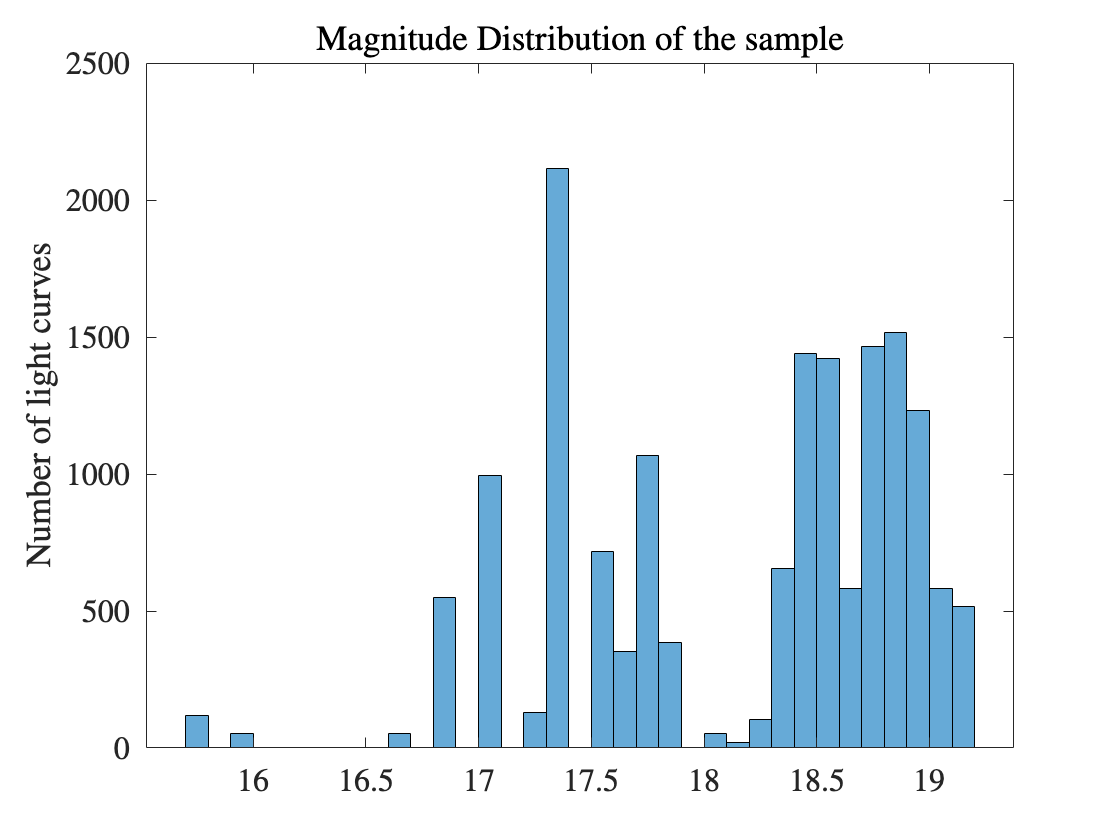

figure();
histogram(ds{:,"Gmag"})
title('Magnitude Distribution of the sample','Interpreter','latex')
ylabel('Number of light curves')

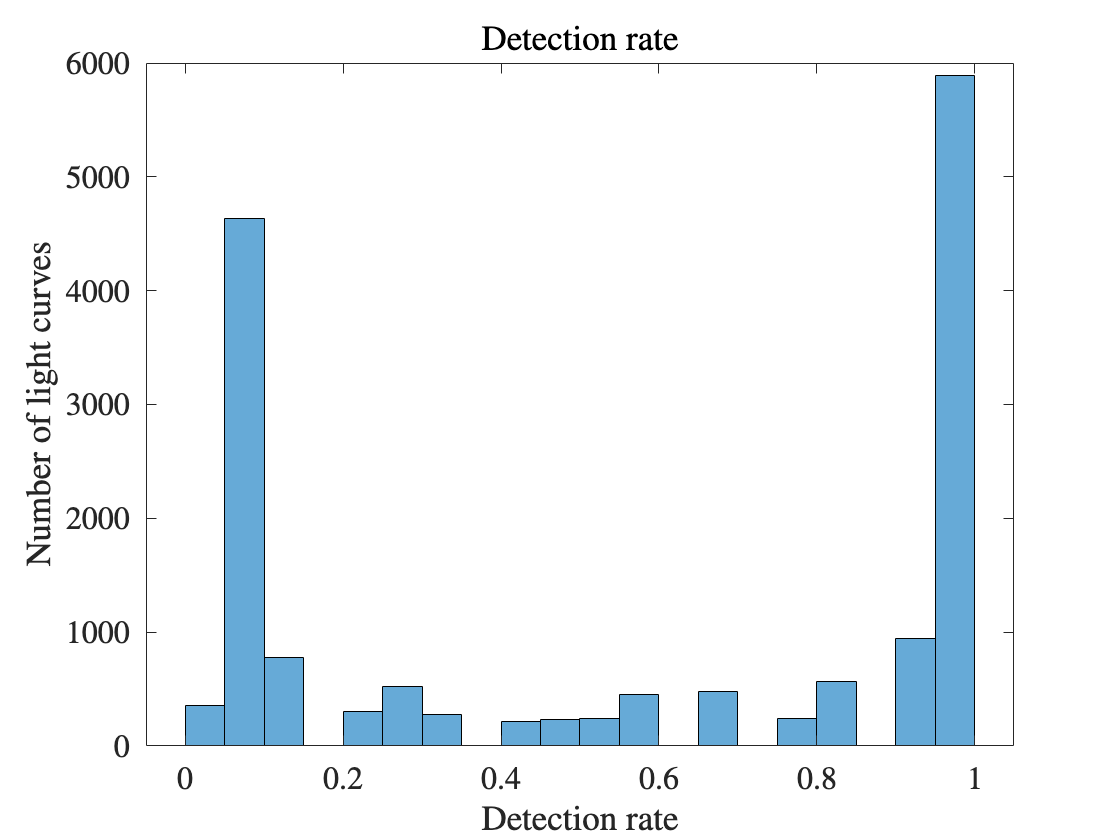

figure();
histogram(ds{:,"N detctions"}/20)
title('Detection rate','Interpreter','latex')
ylabel('Number of light curves')
xlabel('Detection rate')

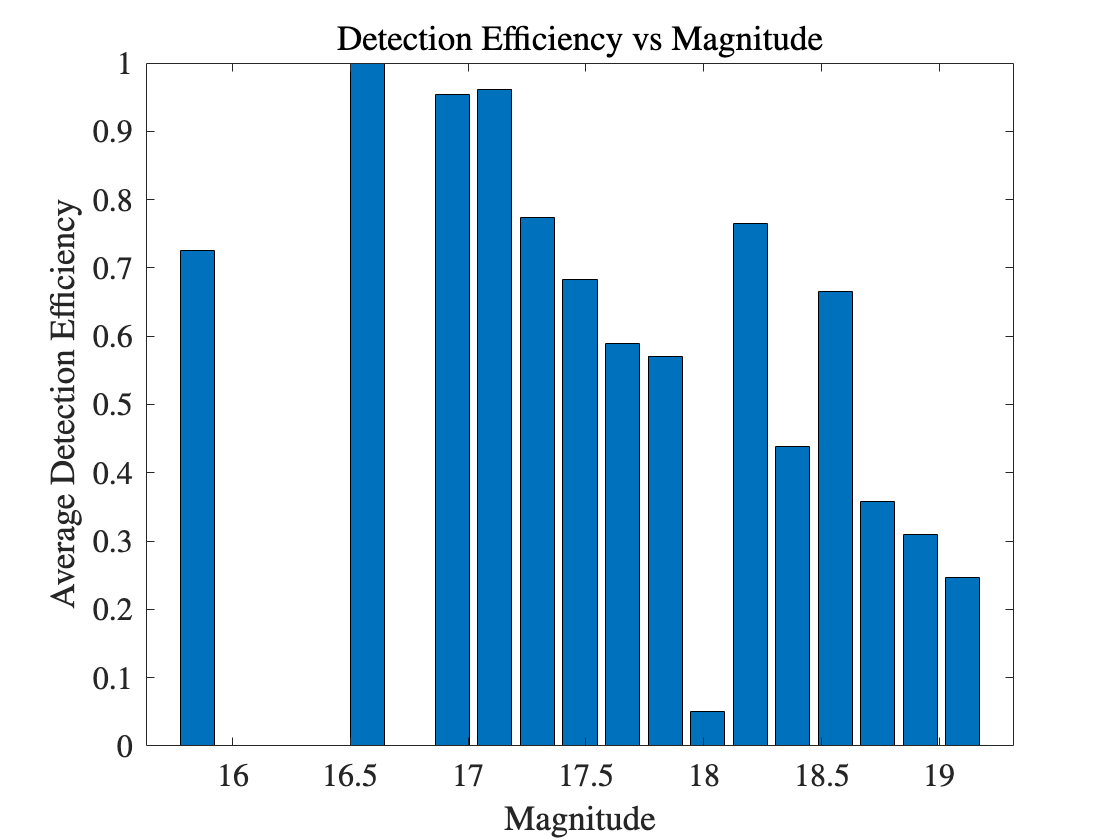

binEdges = linspace(min(ds{:,"Gmag"}), max(ds{:,"Gmag"}), 20);

binCenters = (binEdges(1:end-1) + binEdges(2:end)) / 2;
binEfficiencies = zeros(1, length(binCenters));


for Ibin = 1:length(binCenters)
    binIndices = ds{:,"Gmag"} >= binEdges(Ibin) & ds{:,"Gmag"} < binEdges(Ibin+1);
    binEfficiencies(Ibin) = mean(ds{binIndices,"N detctions"}/20);
end

% Plot the histogram
bar(binCenters, binEfficiencies);
xlabel('Magnitude');
ylabel('Average Detection Efficiency');
title('Detection Efficiency vs Magnitude');

## Flags statistics

It is informative to count the bad flags within our data. Since a no detection will result in a NaN in the light curves as well as a Bad flag. We want to be able to distinguish between the two and to find if most of our NaN in the data are a result of Bad Flags or just no detections.


Args.BadFlags = {'Saturated','Negative','NaN' ,'Spike','Hole','CR_DeltaHT','NearEdge'};
Args.EdgeFlags = {'Overlap'};
Args.runMeanFilterArgs      = {'Threshold',5, 'StdFun','OutWin'};

BadBitCounts = zeros(1,length(Args.BadFlags));

EdgeBitCounts = zeros(1,length(Args.EdgeFlags))

EdgeBitCounts =      0

NaNmag = zeros(Nlc,3);
Contaminated = [];
RA = ds{:,"RA [deg]"};
Dec = ds{:,"Dec [deg]"};
Tp = 0;
EMS = 0;
h = waitbar(0,'Couting Flags.....')

h =   Figure (TMWWaitbar) with properties:

      Number: []
        Name: ''
       Color: [0.96078 0.96078 0.96078]
    Position: [780 502 360 75]
       Units: 'points'

  Show all properties

for Ilc = 1 : Nlc

    MS = ds{Ilc,"Analyzed"}{1};

    if ~isempty(MS)

    Ind = MS.coneSearch(RA(Ilc),Dec(Ilc),6).Ind;

    if ~isempty(Ind)

        Res =  getFlags1(MS,'SrcIdx',Ind);

        Np = MS.Nepoch;
        Tp = Tp + Np;
        
        BadBitCounts =  BadBitCounts + Res.BFcounts;
        EdgeBitCounts =  EdgeBitCounts + Res.EFcounts;


        % get lc


        lc = MS.Data.MAG_PSF(:,Ind);

        NaNmag(Ilc,2) =    sum(isnan(lc)) ;%  sum(isnan(lc));

        NaNmag(Ilc,1) = ds{Ilc,"Gmag"};
        NaNmag(Ilc,3) =      Np ;


       



    else

        Contaminated = [Contaminated ; Ilc];
    end


waitbar(Ilc/Nlc,h,sprintf('Counting Flags in LC %i / %i',Ilc,Nlc))

    else

        EMS = EMS +1;

    end



end

close(h)




fprintf('\nOut of %i Measurements : ',Tp)


Out of 236063 Measurements : 

fprintf('\n%i are contaminated; %.2f %% : \n',sum(Contaminated),sum(Contaminated)/Nlc)

0 are contaminated; 0.00 % : 


fprintf('\n%i Overlap Flags found; %.2f %%\n',EdgeBitCounts,100*EdgeBitCounts/Tp)

7445 Overlap Flags found; 3.15 %


fprintf('\n%i Near Edge Flags found; %.2f %%\n',BadBitCounts(7),100*BadBitCounts(7)/Tp)

581 Near Edge Flags found; 0.25 %


fprintf('\n%i CR_HT Flags found; %.2f %%\n',BadBitCounts(6),100*BadBitCounts(6)/Tp)

152 CR_HT Flags found; 0.06 %


fprintf('\n%i Negative Flags found; %.4f %%\n',BadBitCounts(2),100*BadBitCounts(2)/Tp)

4 Negative Flags found; 0.0017 %


fprintf('\n%i NaN Flags found; %.4f %%\n',BadBitCounts(3),100*BadBitCounts(3)/Tp)

0 NaN Flags found; 0.0000 %


NaN Vs magnitude 

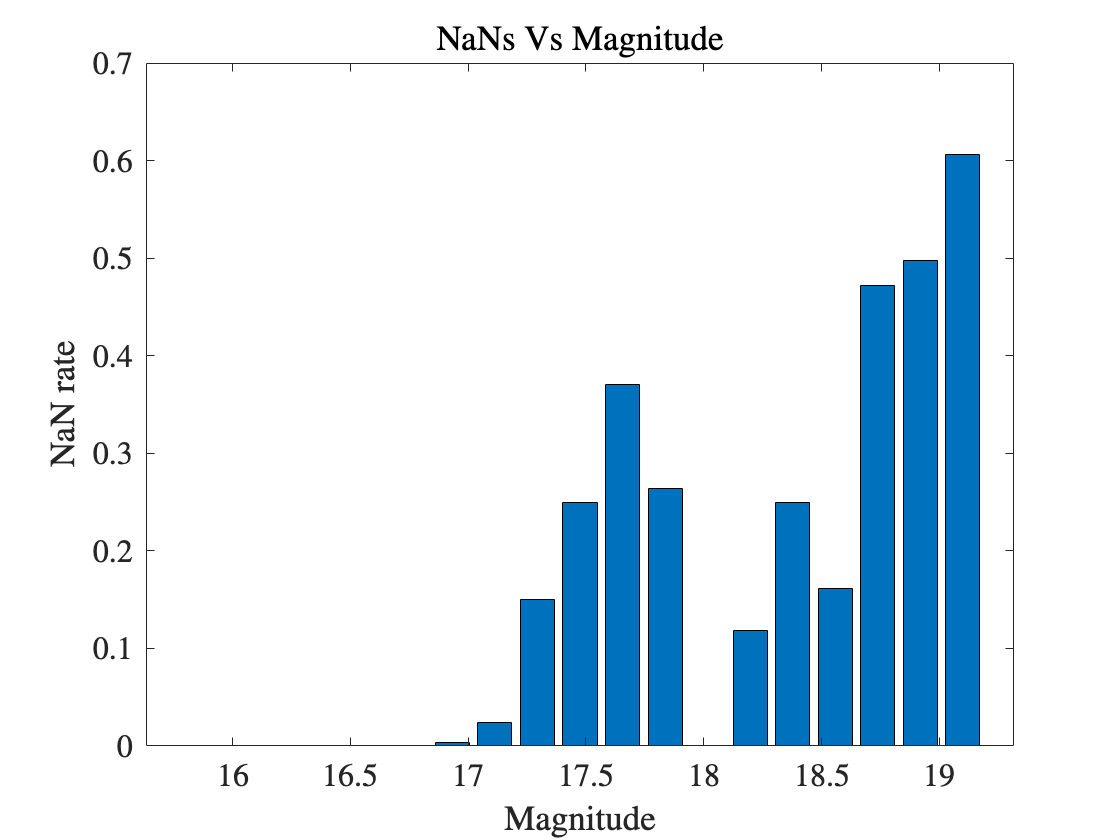



binNaNs = zeros(1, length(binCenters));


for Ibin = 1:length(binCenters)
    binIndices = ds{:,"Gmag"} >= binEdges(Ibin) & ds{:,"Gmag"} < binEdges(Ibin+1);
    binNaNs(Ibin) = sum(NaNmag(binIndices,2))/sum(NaNmag(binIndices,3));
end

% Plot the histogram
bar(binCenters, binNaNs);
xlabel('Magnitude');
ylabel('NaN rate');
title('NaNs Vs Magnitude');

## Detection method

Args.MagField = 'MAG_PSF';
Args.MagErrField = 'MAGERR_PSF';
RA = ds{:,"RA [deg]"};
Dec = ds{:,"Dec [deg]"};
Tp = 0;
EMS = 0;

Lost = zeros(Nlc,2);
Counter = 0;
Detection1 = [];
Detection2 = [];
Detection3 = [];
pdetections1 = 0; 


h = waitbar(0,'Looking for events.....')

h =   Figure (TMWWaitbar) with properties:

      Number: []
        Name: ''
       Color: [0.96078 0.96078 0.96078]
    Position: [780 502 360 75]
       Units: 'points'

  Show all properties

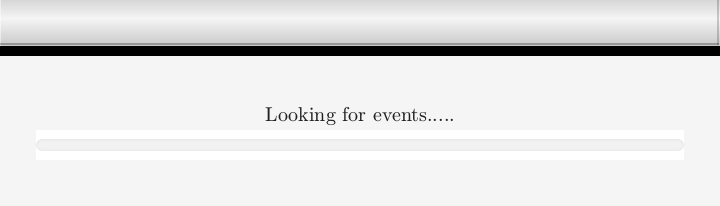

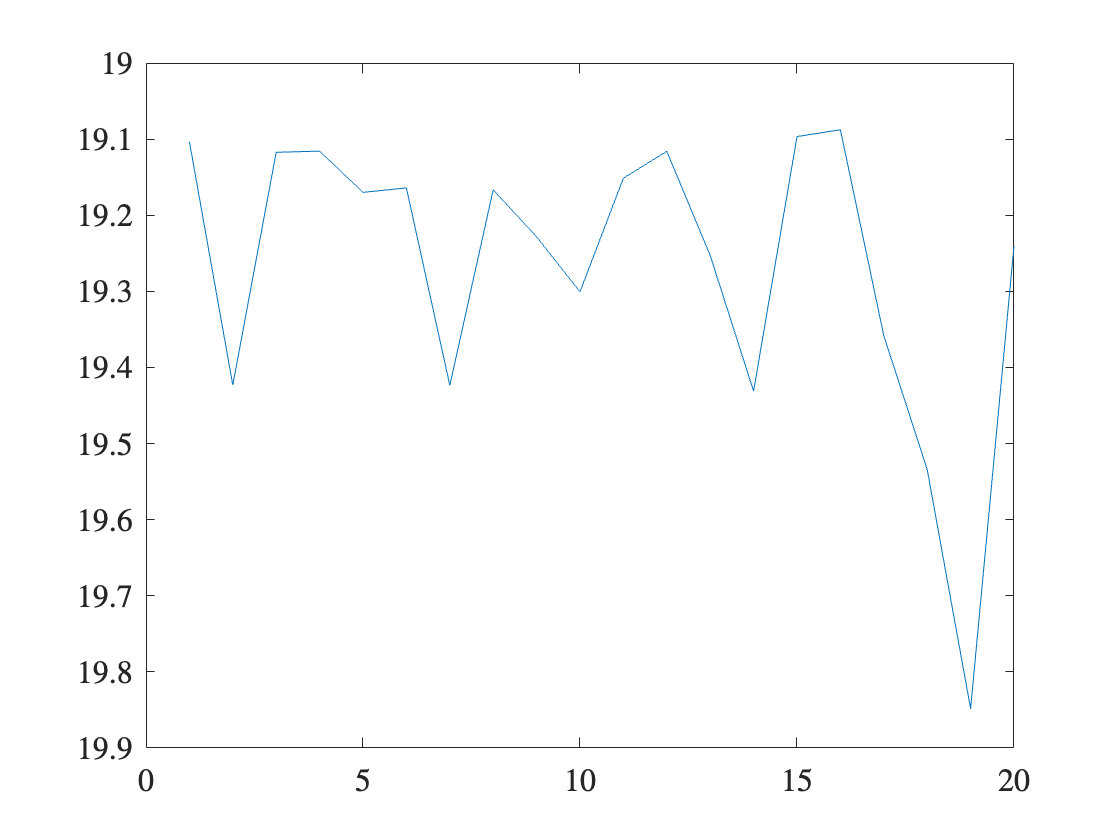

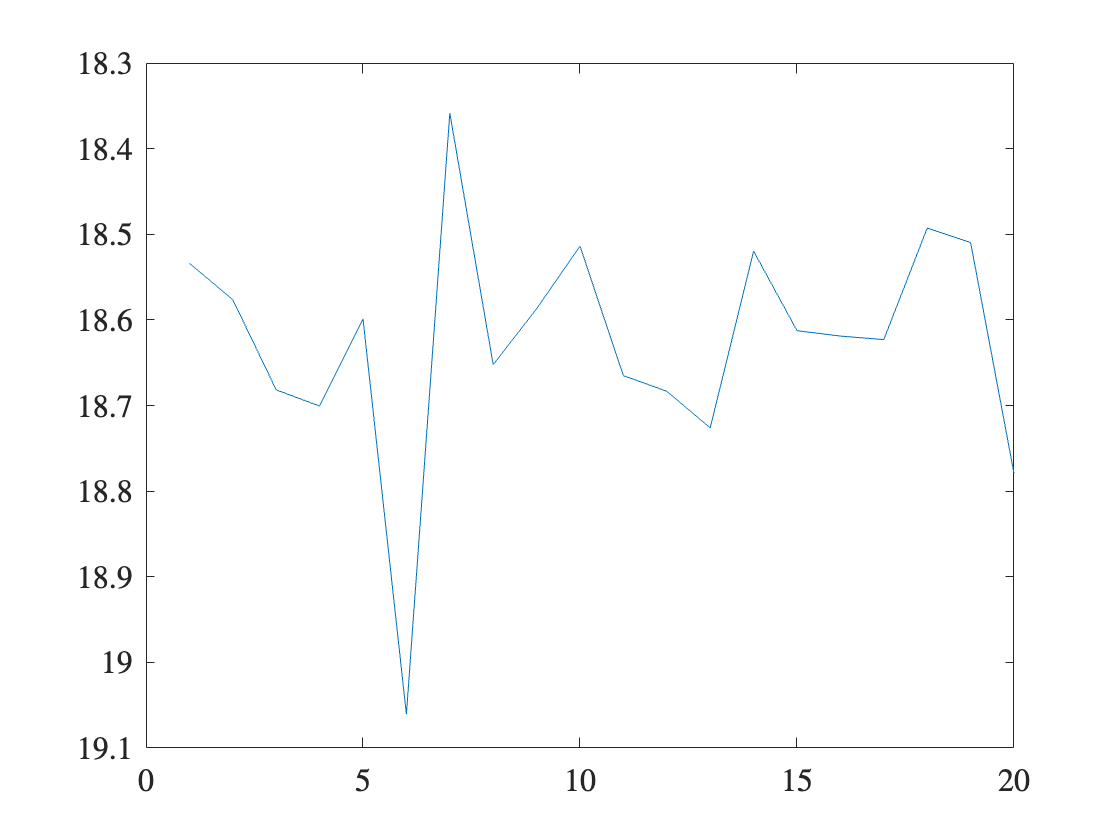

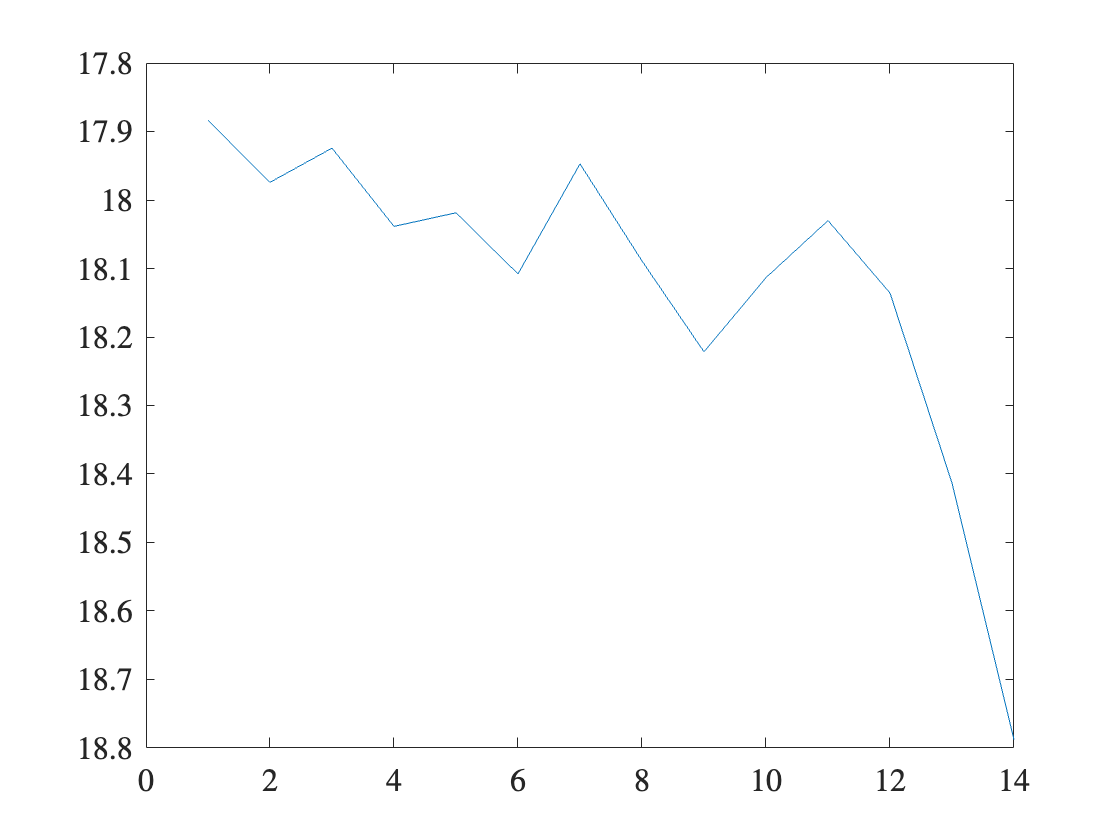

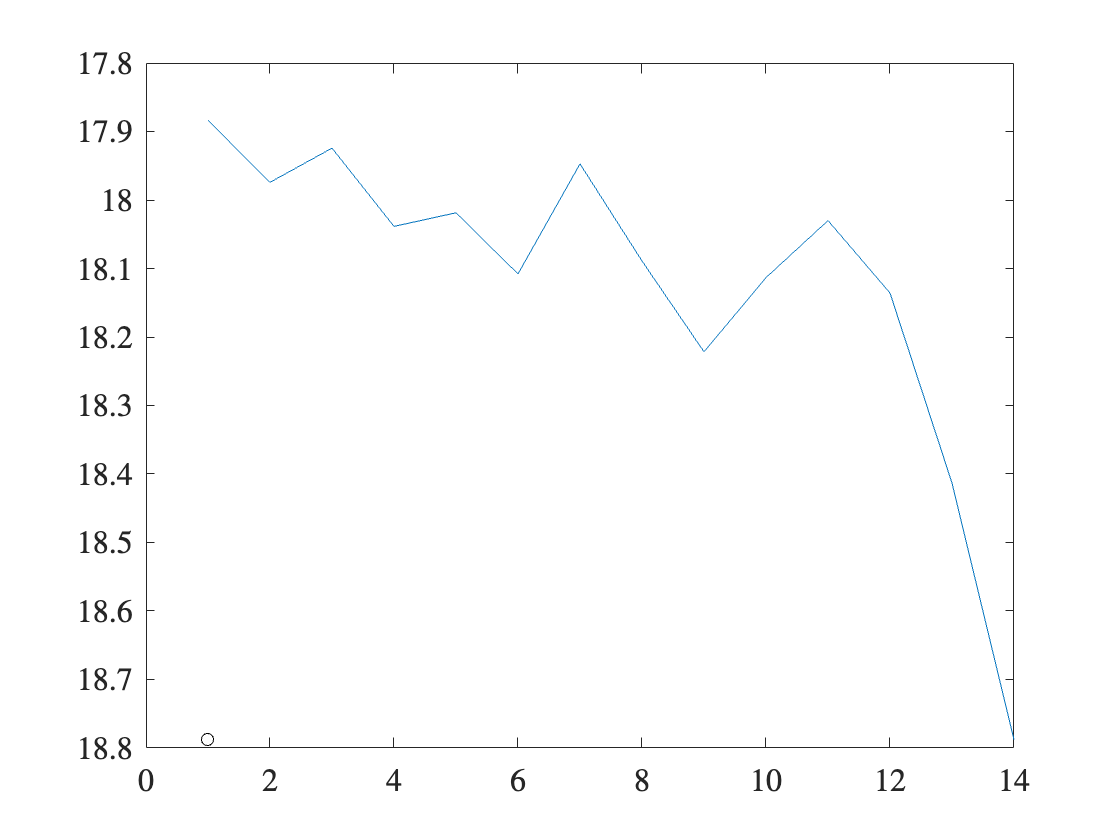

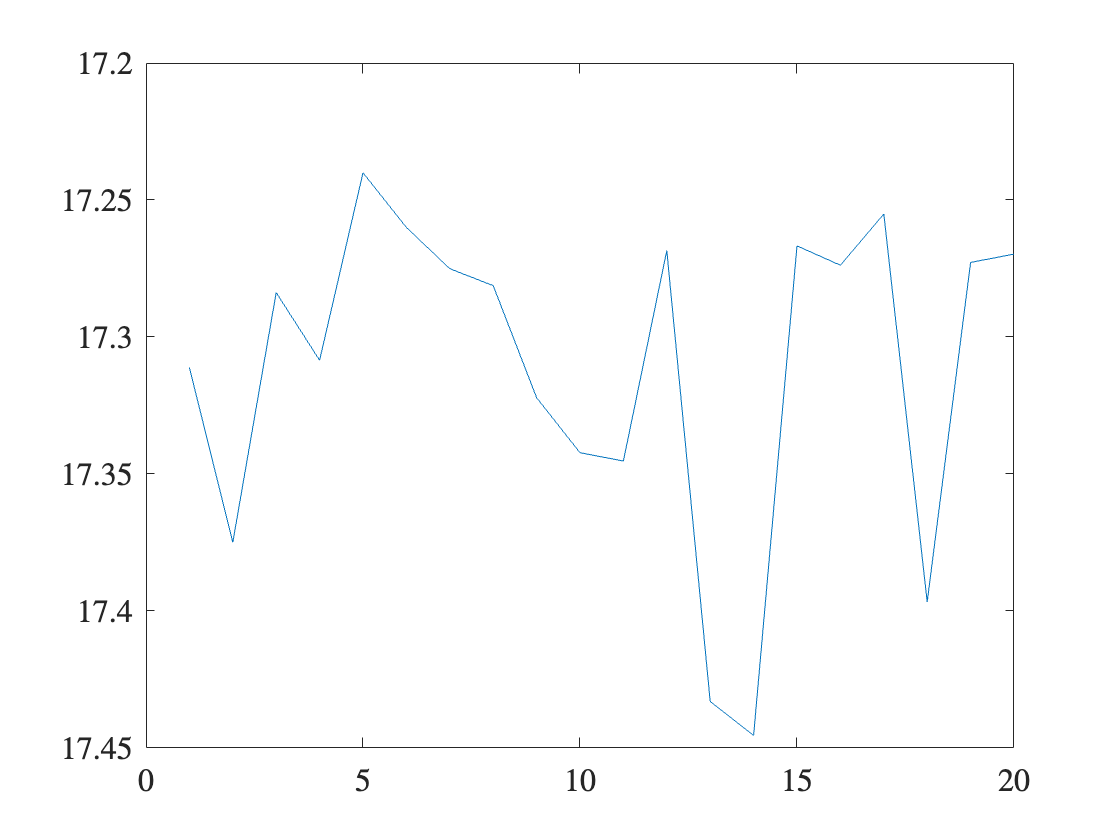

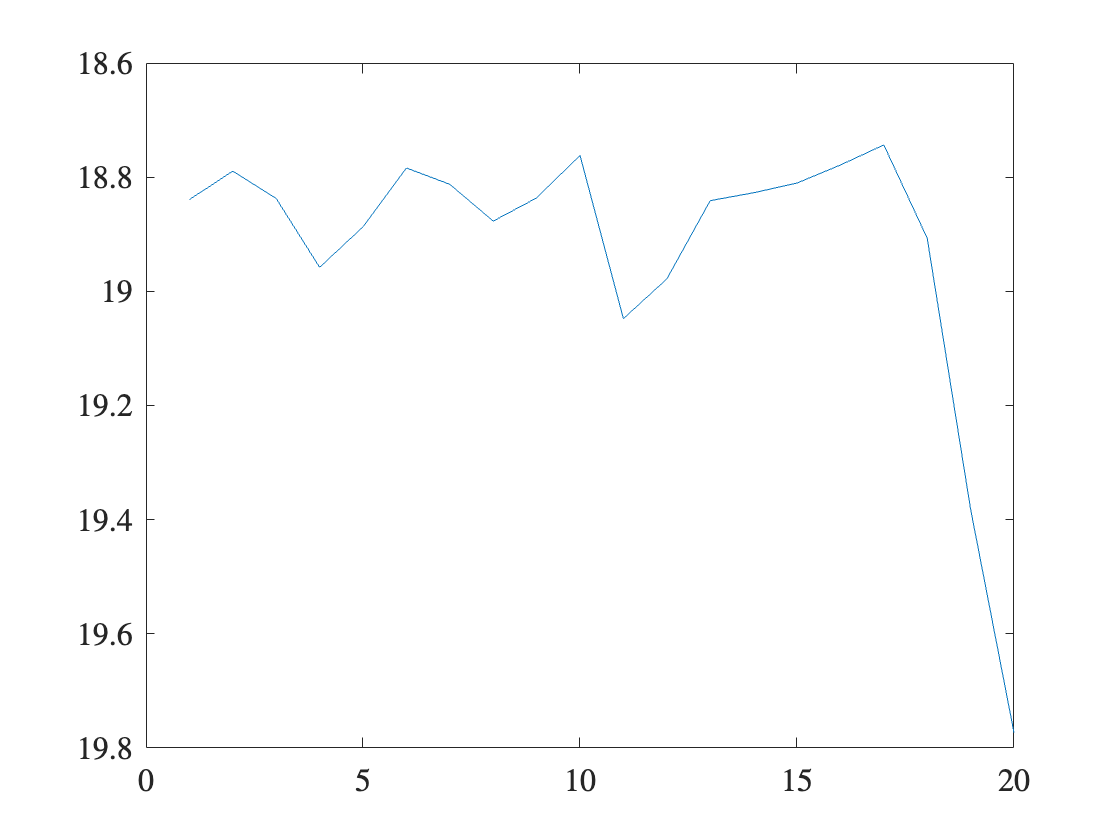

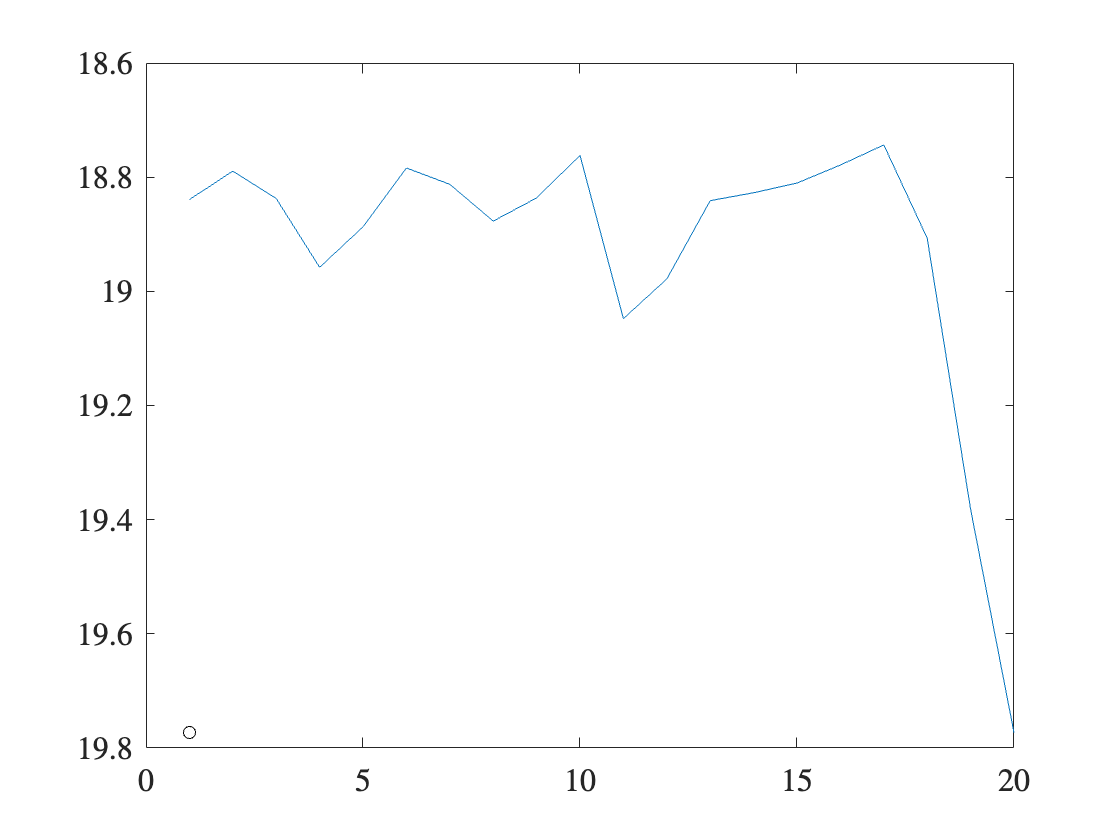

for Ilc = 1 : Nlc

    MS = ds{Ilc,"Analyzed"}{1};



    if ~isempty(MS)
       Np = MS.Nepoch;

    Ind = MS.coneSearch(RA(Ilc),Dec(Ilc),6).Ind;

    if ~isempty(Ind)

    % clean MS

    MMS = MS.setBadPhotToNan('BadFlags',Args.BadFlags, 'MagField','MAG_PSF', 'CreateNewObj',true);
    R = lcUtil.zp_meddiff(MMS,'MagField',Args.MagField,'MagErrField',Args.MagErrField);
    [MMS,ApplyToMagFieldr] = applyZP(MMS, R.FitZP,'ApplyToMagField',Args.MagField);
    % Remove sources with NdetGood<MinNdet
    NdetGood = sum(~isnan(MMS.Data.MAG_PSF), 1);
    if NdetGood(Ind) < 6
        Lost(Ilc,1) =sum(isnan(MS.Data.MAG_PSF(:,Ind))) ;
        Lost(Ilc,2) = 1; 
     

    else
    Fndet    = NdetGood>5;
    %Result.Ndet     = sum(Fndet);
% good stars found
    MMS      = MMS.selectBySrcIndex(Fndet, 'CreateNewObj',false);
 
    % get lc

    % get group lc
        Ind = MMS.coneSearch(RA(Ilc),Dec(Ilc),6).Ind;

        lc = MMS.Data.MAG_PSF(:,Ind);
        [TypicalSD] = clusteredSD1(MMS,'Isrc',Ind);


            NanFlag = false;

        if sum(isnan(lc))>0

            NanFlag = true;
            NaNTemp = zeros(1,Np);

            RES = ds{Ilc,"... "}{1}; %

            t = datetime(MMS.JD,'convertfrom','jd') - seconds(10);

            tt = datetime(RES.JD,'convertfrom','jd');

            [NanDex] = find( isnan(lc) == true);

            for I = 1: length(sum(isnan(lc)))
                
                [~,tmin] = min(abs(t(NanDex(I))-tt));
                lc(NanDex(I)) = RES.LimMag(tmin);
                NaNTemp(NanDex(I)) = 1;

            end

        end

        %% Detection method 1 (2 consecutive points) group sigma
         y_zp  =  lc;
         Med   = median(y_zp,'omitnan');
         % sigma = std(y_zp,'omitnan');
        [newM,newS] = SigmaClips(y_zp,'SigmaThreshold',3,'MeanClip',false);
    % [Threshold,CC] =  clusteredSD(MS,'MedInt',newM,'ExtData',true,'Color',Args.WD.Color(Args.wdIdx));
   % [Threshold,~] =  clusteredSD(MMS,'MedInt',newM,'ExtData',false);
   % threshold = Threshold*2.5;

        threshold = newS*2.5;
        MarkedEvents = [];
        Counter = Counter +1;
        for Ipt = 1 : length(y_zp) - 1
        
                if abs(y_zp(Ipt) -  newM) > threshold
            
                    if abs(y_zp(Ipt+1) - newM) > threshold
                
                        MarkedEvents = [MarkedEvents ; Ipt, Ipt+1];
                
                    end
                end
        end
    
Event = 0 ;
if ~isempty(MarkedEvents)
        Event = 1;
end


                    if Event > 0

                          Detection1 = [Detection1; {Ilc},{MarkedEvents},{lc'} ];
                        
                        pdetections1 = pdetections1 + 1/Nlc;

                        figure();
                        plot(lc);
                        set(gca,'YDir','reverse')

                        if NanFlag

                            Detection1 = [Detection1; {{Ilc},{MarkedEvents},{{lc},{NaNTemp}}} ];
                        
                          pdetections1 = pdetections1 + 1/Nlc;

                        figure();
                        plot(lc);
                        hold on
                        plot(lc(logical(NaNTemp)),'ko')
                        set(gca,'YDir','reverse')





                        end

                    end


                    %% Run mean filter
                   ResFilt = timeSeries.filter.runMeanFilter(lc , Args.runMeanFilterArgs{:}, 'WinSize',2);

                   Result.FlagRunMean = any(ResFilt.FlagCand, 1);
                    if Result.FlagRunMean > 0

                        Detection2 = [Detection2; {Ilc},{ResFilt.FlagCand},{lc'} ];
                        flag = 1;
                        %RMF_detections(Ifilt,1) = RMF_detections(Ifilt,1) + 1/Nlc;
                       

                    end

                    %% Area Detection


            
                    LC = MagToFlux(lc,'ZPflux',10000000000);
    
                    [D,S,dc] = detectEvents(LC,mean(LC),std(LC,'omitnan'),"GetDev",true,"Window",3,'Threshold',2.5);
    
    if sum(D) > 1
       
         Detection3 = [Detection3 ; {Ilc},{D'},{lc'}];
        % DetectionsMB1 = DetectionsMB1 + 1/Nlc;

    end



       

    end

    else

        Contaminated = [Contaminated ; Ilc];
    end


waitbar(Ilc/Nlc,h,sprintf('Counting Flags in LC %i / %i',Ilc,Nlc))

    else

        EMS = EMS +1;

    end



end


close(h)


for I = 1 : length(Detection1)

    if size(Detection1{I,3})==1

    figure()
    if length()
    plot(Detection1{I,3})
    set(gca,'YDir','reverse')

    end
    end
end




for I = 1 : length(Detection2)

EdgeCount =      2

RES = struct with fields:
     BadFlags: {'Saturated'  'Negative'  'NaN'  'Spike'  'Hole'  'CR_DeltaHT'  'NearEdge'}
     BFcounts: [0 0 0 0 0 0 2]
    EdgeFlags: {'Overlap'}
     EFcounts: 2


    if size(Detection1{I,3})==1

    figure()
    if length()
    plot(Detection2{I,3})
    set(gca,'YDir','reverse')

    end
    end
end



## False positive

Args.MagField = 'MAG_PSF';
Args.MagErrField = 'MAGERR_PSF';
RA = ds{:,"RA [deg]"};
Dec = ds{:,"Dec [deg]"};
Tp = 0;
EMS = 0;

LostFPR = zeros(Nlc,2);

h =   Figure (TMWWaitbar) with properties:

      Number: []
        Name: ''
       Color: [0.96078 0.96078 0.96078]
    Position: [780 502 360 75]
       Units: 'points'

  Show all properties

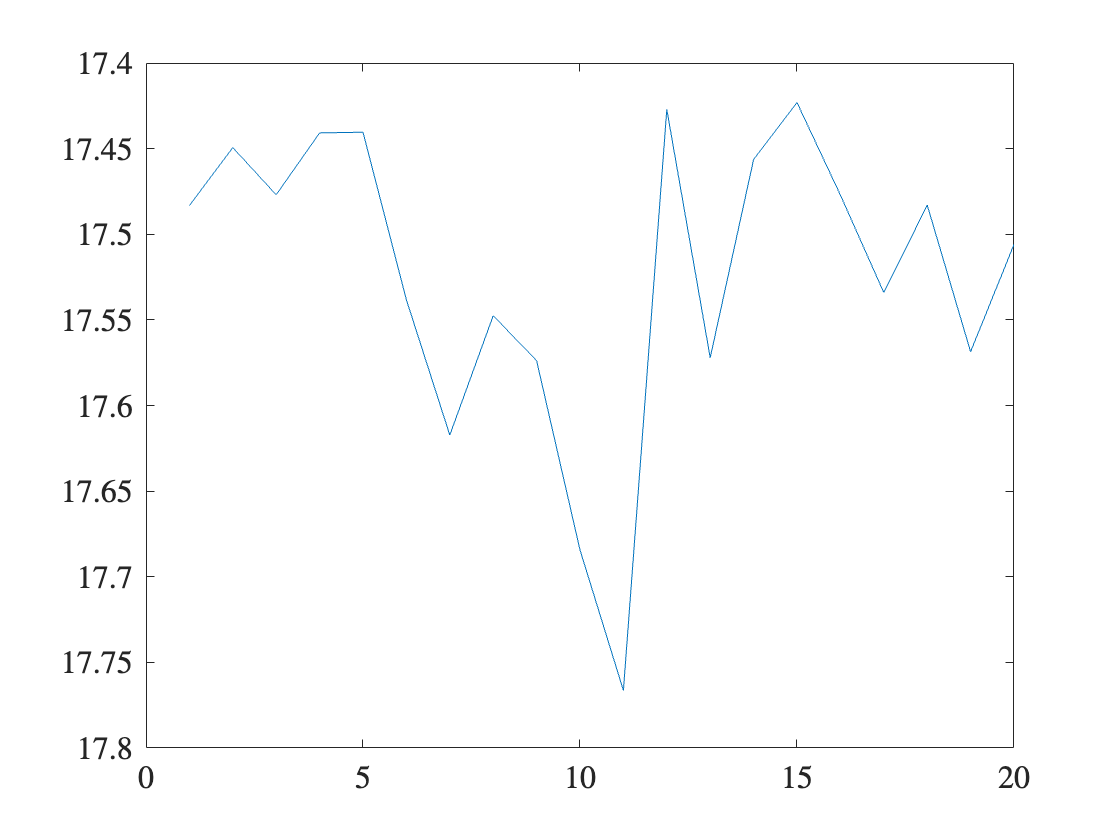

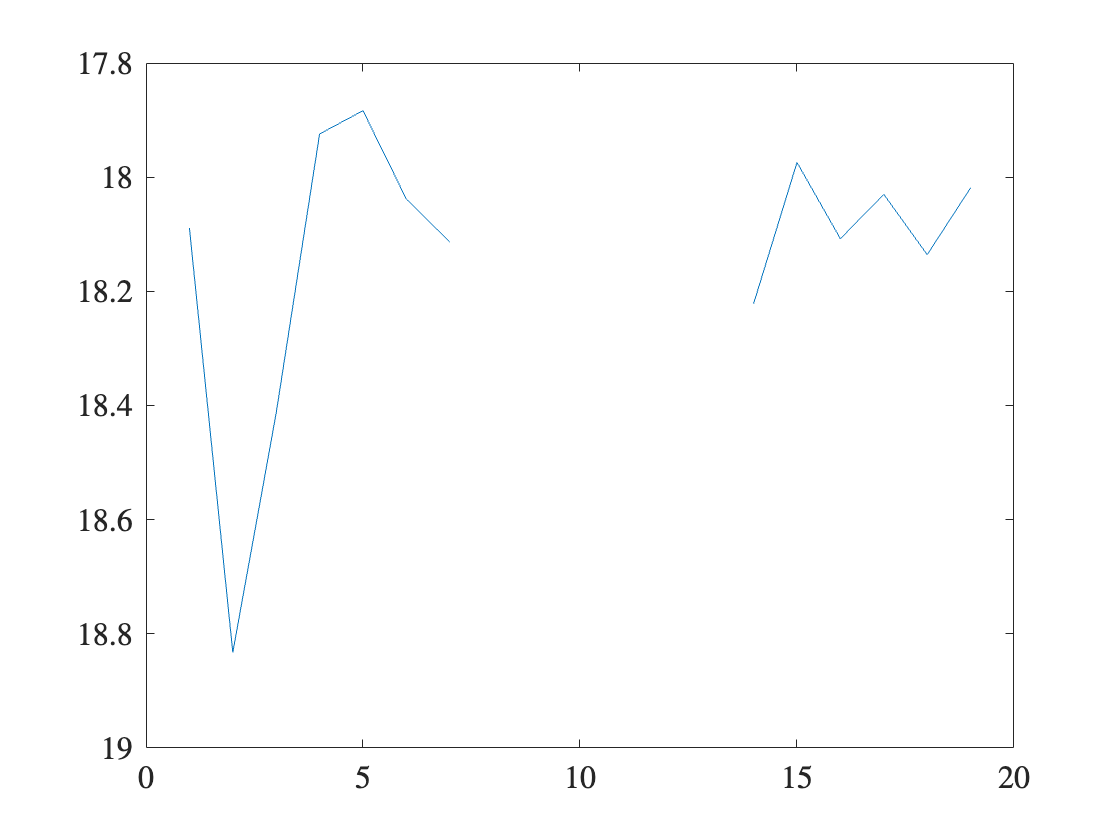

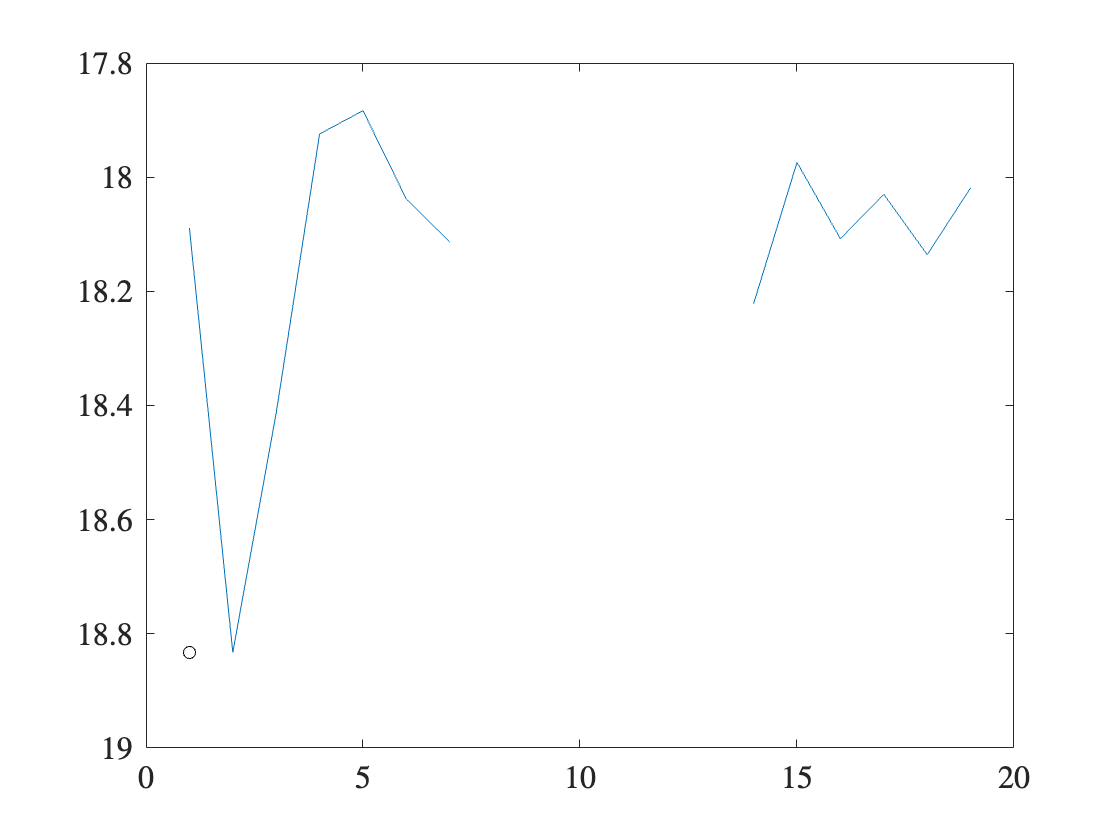

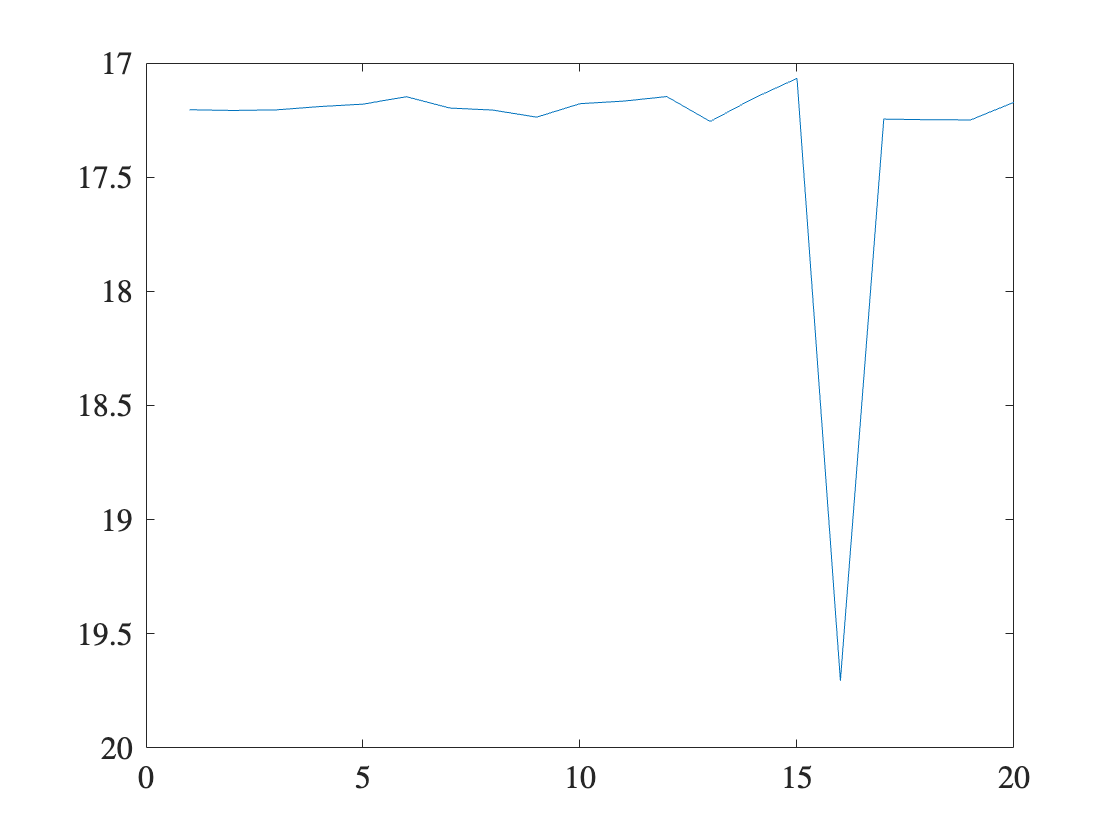

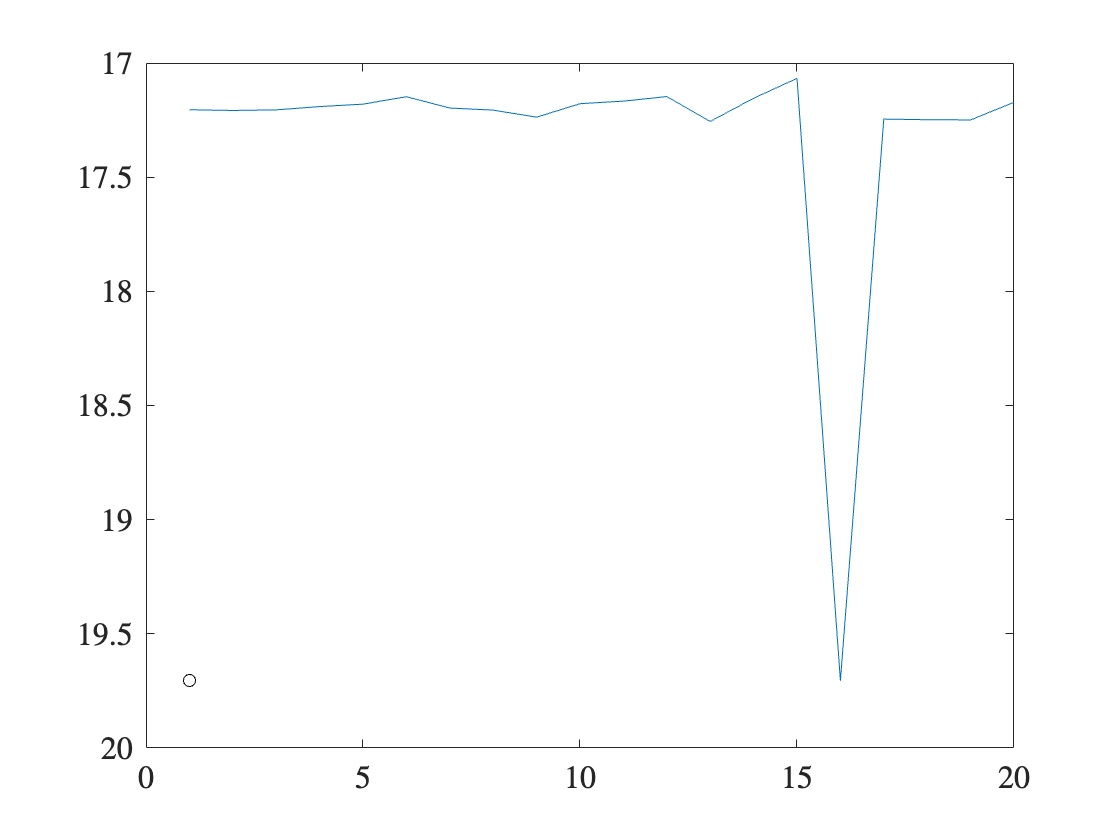

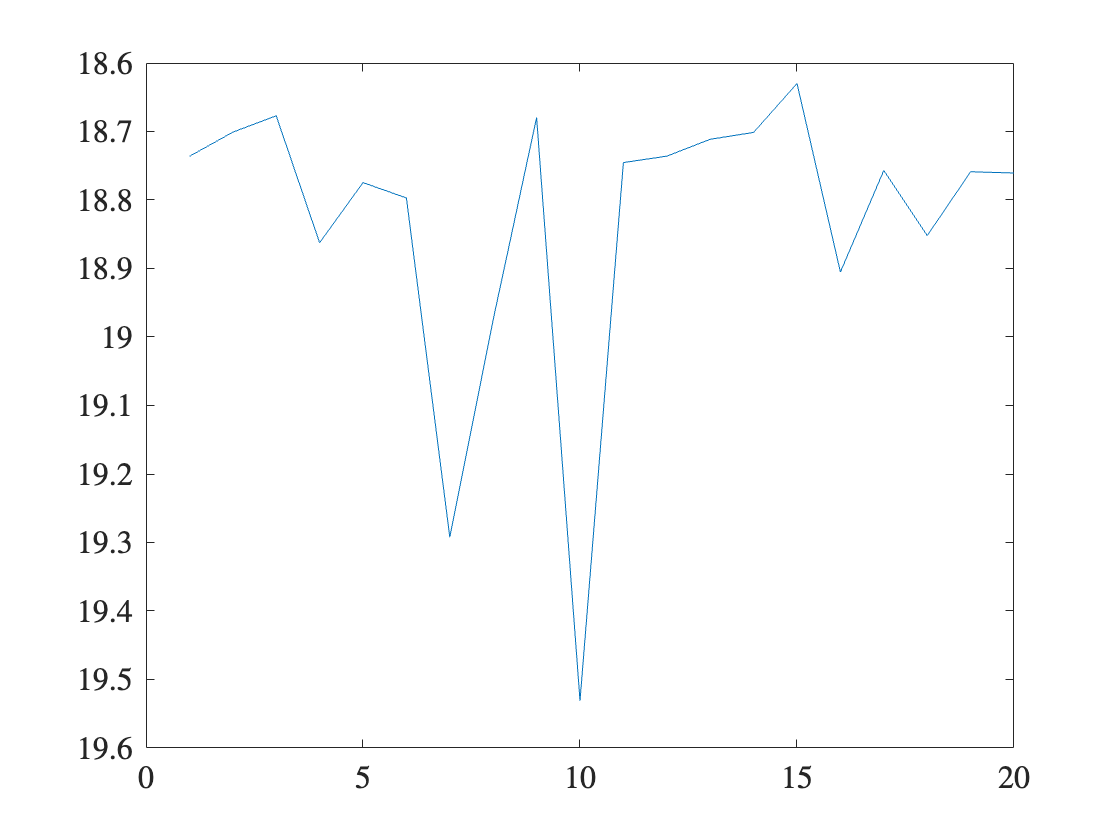

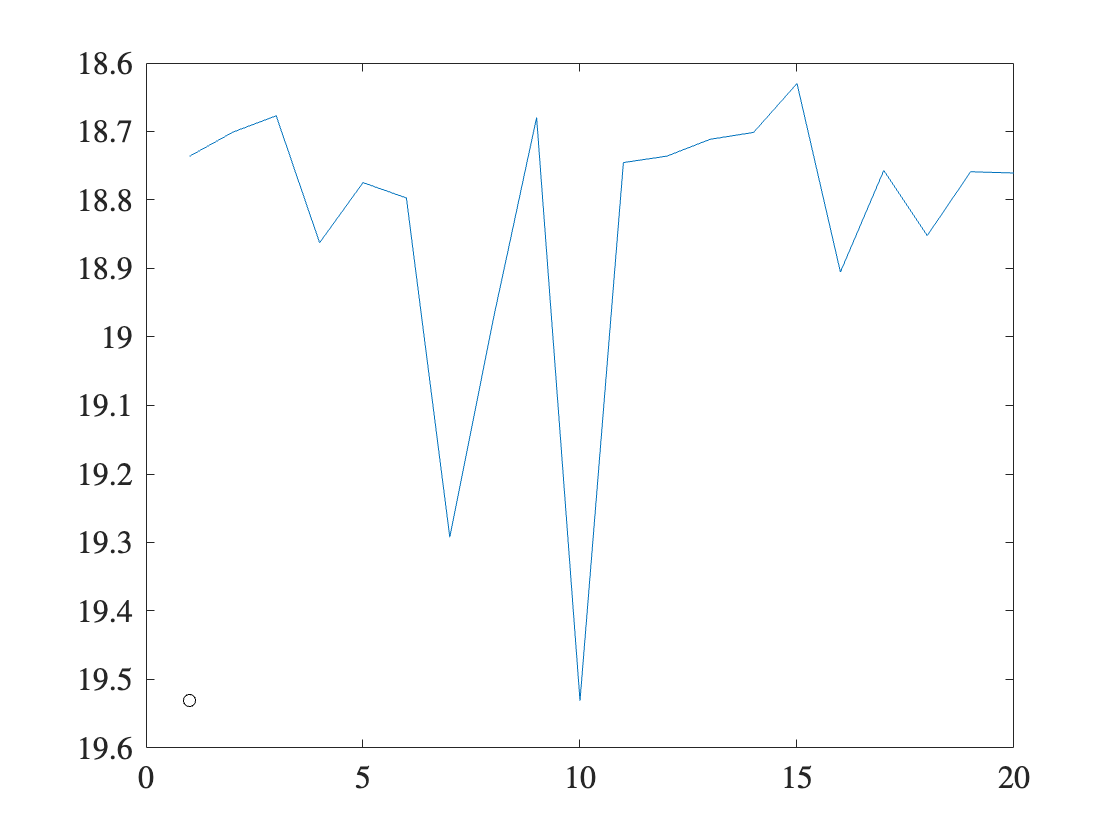

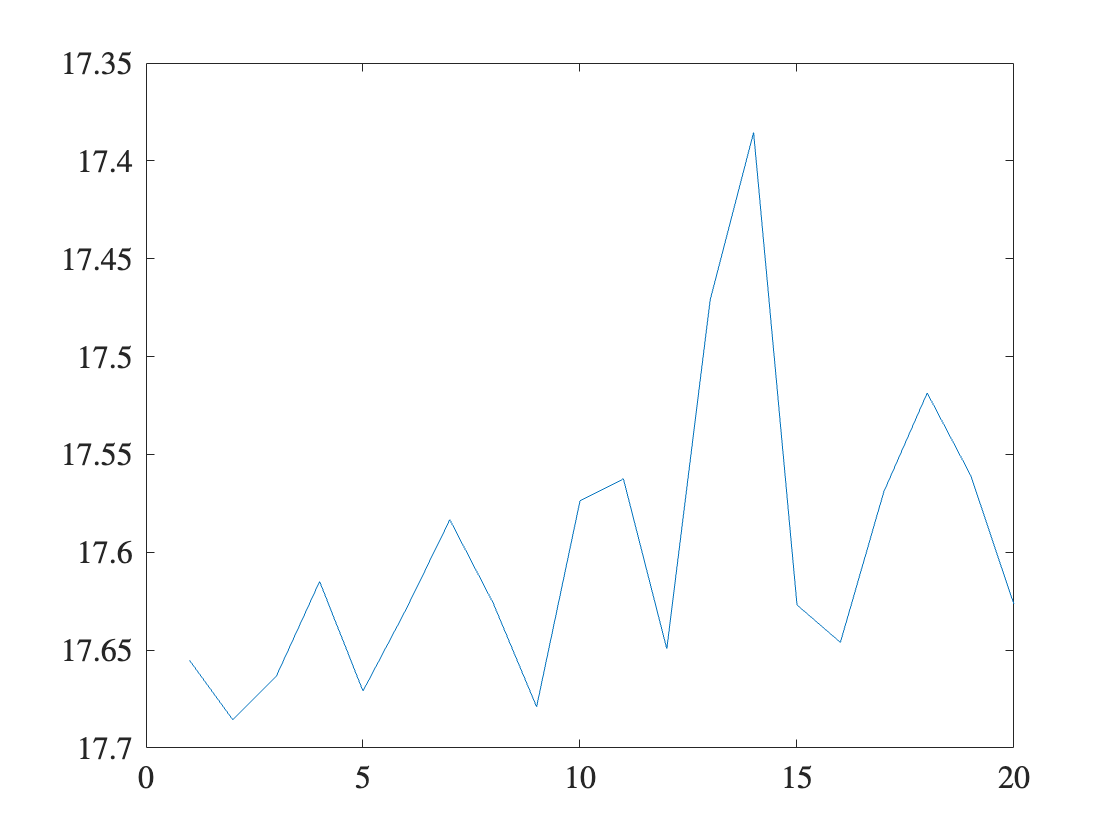

CounterFPR = 0;
fDetection1 = [];
fDetection2 = [];
fDetection3 = [];



h = waitbar(0,'Looking for events.....')
for Ilc = 1 : Nlc

    MS = ds{Ilc,"Analyzed"}{1};
    

    if ~isempty(MS)

Method 1 26 Detections

       Np = MS.Nepoch;

Method 1 22 FPR

Method 2 17 Detections

    Ind = MS.coneSearch(RA(Ilc),Dec(Ilc),6).Ind;

Method 2 13 FPR

Method 3 30 Detections

    if ~isempty(Ind)

Method 3 25 FPR


    % clean MS

    MMS = MS.setBadPhotToNan('BadFlags',Args.BadFlags, 'MagField','MAG_PSF', 'CreateNewObj',true);
    R = lcUtil.zp_meddiff(MMS,'MagField',Args.MagField,'MagErrField',Args.MagErrField);
    [MMS,ApplyToMagFieldr] = applyZP(MMS, R.FitZP,'ApplyToMagField',Args.MagField);
    % Remove sources with NdetGood<MinNdet
    NdetGood = sum(~isnan(MMS.Data.MAG_PSF), 1);
    if NdetGood(Ind) < 6
        LostFPR(Ilc,1) =sum(isnan(MS.Data.MAG_PSF(:,Ind))) ;
        LostFPR(Ilc,2) = 1; 
     

    else
    Fndet    = NdetGood>5;
    %Result.Ndet     = sum(Fndet);
% good stars found
    MMS      = MMS.selectBySrcIndex(Fndet, 'CreateNewObj',false);
 
    % get lc

    % get group lc
        Ind = MMS.coneSearch(RA(Ilc),Dec(Ilc),6).Ind;

        randIndex = randperm(Np);

        lc = MMS.Data.MAG_PSF(randIndex,Ind);
        [TypicalSD] = clusteredSD1(MMS,'Isrc',Ind);


            NanFlag = false;

        if sum(isnan(lc))>0

            NanFlag = true;
            NaNTemp = zeros(1,Np);

            RES = ds{Ilc,"... "}{1}; %

            t = datetime(MMS.JD,'convertfrom','jd') - seconds(10);

            tt = datetime(RES.JD,'convertfrom','jd');

            [NanDex] = find( isnan(lc) == true);

            for I = 1: length(sum(isnan(lc)))
                
                [~,tmin] = min(abs(t(NanDex(I))-tt));
                lc(NanDex(I)) = RES.LimMag(tmin);
                NaNTemp(NanDex(I)) = 1;

            end

        end

        %% Detection method 1 (2 consecutive points) group sigma
         y_zp  =  lc;
         Med   = median(y_zp,'omitnan');
         % sigma = std(y_zp,'omitnan');
        [newM,newS] = SigmaClips(y_zp,'SigmaThreshold',3,'MeanClip',false);
    % [Threshold,CC] =  clusteredSD(MS,'MedInt',newM,'ExtData',true,'Color',Args.WD.Color(Args.wdIdx));
   % [Threshold,~] =  clusteredSD(MMS,'MedInt',newM,'ExtData',false);
   % threshold = Threshold*2.5;

        threshold = newS*2.5;
        MarkedEvents = [];
        Counter = Counter +1;
        for Ipt = 1 : length(y_zp) - 1
        
                if abs(y_zp(Ipt) -  newM) > threshold
            
                    if abs(y_zp(Ipt+1) - newM) > threshold
                
                        MarkedEvents = [MarkedEvents ; Ipt, Ipt+1];
                
                    end
                end
        end
    
Event = 0 ;
if ~isempty(MarkedEvents)
        Event = 1;
end


                    if Event > 0

                          fDetection1 = [fDetection1; {Ilc},{MarkedEvents},{lc} ];
                        
                        pdetections1 = pdetections1 + 1/Nlc;

                        figure();
                        plot(lc);
                        set(gca,'YDir','reverse')

                        if NanFlag

                            fDetection1 = [fDetection1; {{Ilc},{MarkedEvents},{{lc},{NaNTemp}}} ];
                        
                          pdetections1 = pdetections1 + 1/Nlc;

                        figure();
                        plot(lc);
                        hold on
                        plot(lc(logical(NaNTemp)),'ko')
                        set(gca,'YDir','reverse')





                        end

                    end


                    %% Run mean filter
                   ResFilt = timeSeries.filter.runMeanFilter(lc , Args.runMeanFilterArgs{:}, 'WinSize',2);

                   Result.FlagRunMean = any(ResFilt.FlagCand, 1);
                    if Result.FlagRunMean > 0

                        fDetection2 = [fDetection2; {Ilc},{ResFilt.FlagCand} ];
                        flag = 1;
                        %RMF_detections(Ifilt,1) = RMF_detections(Ifilt,1) + 1/Nlc;
                       

                    end

                    %% Area Detection


            
                    LC = MagToFlux(lc,'ZPflux',10000000000);
    
                    [D,S,dc] = detectEvents(LC,mean(LC),std(LC,'omitnan'),"GetDev",true,"Window",3,'Threshold',2.5);
    
    if sum(D) > 1
       
         fDetection3 = [fDetection3 ; {Ilc},{D'}];
        % DetectionsMB1 = DetectionsMB1 + 1/Nlc;

    end



       

    end

    else

        Contaminated = [Contaminated ; Ilc];
    end


waitbar(Ilc/Nlc,h,sprintf('Counting Flags in LC %i / %i',Ilc,Nlc))

    else

        EMS = EMS +1;

    end



end

close(h)


fprintf('Method 1 %i Detections',length(Detection1))
fprintf('Method 1 %i FPR',length(fDetection1))
fprintf('Method 2 %i Detections',length(Detection2))
fprintf('Method 2 %i FPR',length(fDetection2))
fprintf('Method 3 %i Detections',length(Detection3))
fprintf('Method 3 %i FPR',length(fDetection3))

- Detection Vs magnitude

- 90% Detection.

- Exposure

Functions

%%
function [Res] = getLcfromMs

end